# SymbolicProblem

Illustrates how to solve a calculus problem with MATLAB [symbolic computations](https://www.mathworks.com/help/symbolic/performing-symbolic-computations.html). For a general introduction, see [Learn Calculus in the Live Editor.](https://www.mathworks.com/help/symbolic/examples/learn-calculus.html)

Author: Duncan Carlsmith

Problem statement:

Water is poured into a container that has a leak. The mass $m$ of the water is given as a function of time $t$ by


$$m=A\sqrt{t}-Bt+C$$


with $t>0$, $m$ in grams, $t$ in seconds, and $A$, $B$, and $C$ are positive constants. In terms of $A$, $B$, and $C$, (a) find a formula for the rate of mass change as a function of $t$, (b) At what time is the water mass greatest, and (c) what is that greatest mass?

Ref: This problem is from Halliday, Resnick, and Walker University Physics (10e).

Comment: This exercise in calculus entails no principles of physics.  The quantity $m$ could represent the number of people on a bus, or the national debt. The specification of units in the problem statement provides no needed information. Fully analytic expressions are valid whatever consistent units are used although the values of the variables depend upon units in application.

(a) The rate of change of a function of time is the derivative of the function with respect to time.

Clear the workspace and define MATLAB symbolic variables for independent variables. 

%clear
syms t A B C

Define the function. The quantities on the right hand side were defined and are recognized as symbols so MATLAB creates a symbolic expression and we catch that as `m`. [Check its type in the workspace pane.] This process emulates what a person does when writing this sort of expression on paper by hand.

m=A*t^(1/2)-B*t+C;

Now if A,B and C are positive numbers, the 1st  term is an increasing function of time (it might represent flow in a controlled flow input pipe) and the second term a decreasing function of time (it might represent flow in a controlled flow output pipe), and the 2nd term will dominate for large times because $t$ will become sufficiently larger than $\sqrt(t)$ at some $t$, whatever the values of $A$ and $B$.

Let's illustrate by substituting into m for `A, B, C` some positive values using [subs](https://www.mathworks.com/help/symbolic/subs.html).

m_210=subs(m,[A B C],[2 1 0])

$$m\_210 = 2\,\sqrt{t}-t$$

Next use [fplot](https://www.mathworks.com/help/matlab/ref/fplot.html) to plot the symbolic function over an interval of time. The function `fplot` will plot a function using points and lines of sufficient density to best visualize the continuum of value pairs represented by a continuous function. In contrast, the MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html) is designed to visualize vectors of data, y versus x or x values versus index values. Such vectors might be estimates of values of some function, but need not be.` plot` defaults to join points with lines but these lines may not correspond to any function, just guide (or misguide) the eye so don't use lines when plotting data. They just cloud the picture. When using plot with data, instead, be explicit about using points by picking a symbol, e.g. `>>plot(x,y,'.')`. ] 

**Tip:** MATLAB supports functions with a variable number of input arguments and variable input types, unlike many interpreted or compiled languages. This means you can supply a function like fplot various data and it will attempt to do what you want. Our call sends a symbol (`m_210`) not a function. The code figures that out. To see exactly how, use `>> type fplot`. This `fplot `functionality requires the Symbolic Math toolbox, not vanilla MATLAB. Another plotting function [ezplot](https://www.mathworks.com/help/symbolic/ezplot.html) now deprecated has the ability to interpret and plot a variety of inputs.

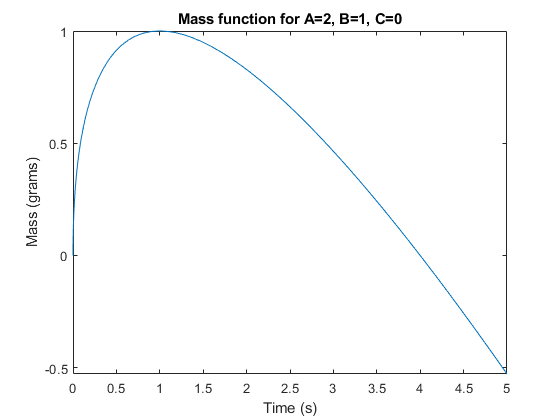

interval=[0 5];
fplot(m_210,interval)
xlabel('Time (s)');ylabel('Mass (grams)');
title('Mass function for A=2, B=1, C=0')

We observe a local maximum close to $t=1$.

Now we are asked for the rate of change of mass, i.e. the derivative of `m`. Take the derivative using [`diff`](https://www.mathworks.com/help/symbolic/diff.html) which takes a symbolic expression as an input and uses rules of calculus to return a symbolic expression expressing the derivative. MATLAB knows all the rules and probably has a thick integral table up its sleeve just in case. It returns a symbolic expression we catch as `m_t.`

**Tip**: Subscripts are a compact way to express derivatives. The expression $\dot m$ for example is ambiguous if $m$ is a function not just of time but also of additional variables/parameters. Suppose m=m(x,y). Then we can define

$m_x\equiv{{\partial m}\over{\partial x}}$, $m_y\equiv {{\partial m}\over {\partial y}}$, $m_{xx}={{\partial^2m}\over{\partial x^2}}$, etc.

So it can be handy to use MATLAB symbols that emulate this practice.

m_t=diff(m)

$$m\_t = \frac{A}{2\,\sqrt{t}}-B$$

Done. Wait. Derivative with respect to which variable? All the symbols on the right hand side of the definition of `m` are equivalent. Not told otherwise, MATLAB `diff` makes a best guess, choosing a variable in a list it associated with the function m when `m` was defined. We were a bit lucky here. We can see the list of variables associated with `m` using [`symvar`](https://www.mathworks.com/help/matlab/ref/symvar.html).

symvar(m)

$$ans = \left(\begin{array}{cccc} A & B & C & t \end{array}\right)$$

MATLAB `diff `guesses that the most common of the commonly used variables like x or t is likely what you mean to differentiate with respect to (unless you say otherwise) if one or more commonly used variables appears in the list. If there is no such obvious variable, it will pick the first variable in the list. Thanks MATLAB, but it is best to be explicit. 

**Tip:** Try to stick to standard notation in physics. When I see $t$, I expect it to mean time or thickness, not for example weight, and $F_x$ should mean the $x$-component of a force not say something like air density.

**Try this**: We can just as well differentiate with respect to some other variable. Compare the outputs from the following commands. Are the outputs what you expect? We are actually calculating a [partial derivative](https://en.wikipedia.org/wiki/Derivative#Partial_derivatives) of $m(t,A,B,C)$ in each case.

m_t=diff(m,t),m_A=diff(m,A)

$$m\_t = \frac{A}{2\,\sqrt{t}}-B$$

$$m\_A = \sqrt{t}$$

 (b) At what time is the water mass greatest?

It sounds like the mass function has a single maximum as we observed in our numerical example above. Since at an extremum (minimum or maximum) the derivative vanishes, we must solve the equation `m_t=0` for `t`.

Define a [symbolic equation](https://www.mathworks.com/help/symbolic/eq.html) using the == operator, and catch that equation with a random name, say eqn. 

**Tip**: If you open `eqn` by double-clicking it in the workspace, you will see that the == operator simply took the symbol to its left and the symbol to its right and constructed a symbolic expression of the form `L-R=0`.

eqn = m_t==0

$$eqn = \frac{A}{2\,\sqrt{t}}-B=0$$

Solve the equation with [`solve`](https://www.mathworks.com/help/symbolic/solve.html).

tmax=solve(eqn)

$$tmax = \frac{A^{2}}{4\,B^{2}}$$

**Tip**: We could have condensed the last two commands as follows.

tmax=solve(m_t==0 )

$$tmax = \frac{A^{2}}{4\,B^{2}}$$

The way to understand a nested MATLAB command like that is to start with the innermost expression (m_t==0) and evaluate it , then, think about its result as the input to the enclosing command. For clarity, it is best to spell out the operations one by one, rather than nest them. Make the result of each operation a workspace variable that you can look at to be sure all is well.

Done. Wait. We didn't tell `solve` what variable to solve for. We got lucky again. Best to be explicit.

solve(eqn,t), solve(eqn,A)

$$ans = \frac{A^{2}}{4\,B^{2}}$$

$$ans = 2\,B\,\sqrt{t}$$

For $[A,B,C]=[2,1,0]$, the maximum appears at time 1 according to this symbolic result, as observed in the plot above, if you substitute for A, B, and C in your head. Use subs to substitute in to check if you want to.

(c) What is that greatest mass?

Well, the greatest mass is the value of $m(t)$ when t=tmax. So we must  in `m(t) `for `t `substitute `tmax`. We can use [subs](https://www.mathworks.com/help/symbolic/subs.html) to do the substitution, now of symbols. (Note the order of the input arguments to `subs` matches the rather backwards-sounding English description I've used.)

m_max=subs(m,t,tmax)

$$m\_max = C+A\,\sqrt{\frac{A^{2}}{4\,B^{2}}}-\frac{A^{2}}{4\,B}$$

This expression is correct but evidently can be simplified. We can simplify using, um, you guessed it,  [simplify](https://www.mathworks.com/help/symbolic/simplify.html).

m_max1=simplify(m_max)

$$m\_max1 = \frac{A^{2}+4\,B\,C}{4\,B}$$

Hmm. Wait. That didn't help. The reason is the square root can return multiple values and `simplify` doesn't quite know how to proceed. In fact, at this point MATLAB doesn't know that `A`, `B`, and `C` are supposed to represent positive real values. They could be real numbers of any sign or even complex numbers or matrices. They are just symbols/characters that obey ordinary rules of algebra by default. For $A<0$ and $B>0$ and $C$ any value, there is no maximum in fact. We can tell `simplify` to ignore imaginary solutions to coax out a simplified solution.

m_max2=simplify(m_max,'Steps',4,'IgnoreAnalyticConstraints',1)

$$m\_max2 = C+\frac{A^{2}}{4\,B}$$

We can also be explicit and tell MATLAB our assumptions, namely that these symbols stand for real positive values, using [assume](https://www.mathworks.com/help/symbolic/assume.html), before simplifying.

assume(A,'real');assume(A,'positive');
assume(B,'real');assume(B,'positive');
assume(C,'real');assume(C,'positive');
m_max=simplify(subs(m,t,tmax));

m_tt=diff(m, 2)

$$m\_tt = -\frac{A}{4\,t^{3/2}}$$

sub = subs(m_tt, t, tmax)

$$sub = -\frac{A}{4\,{\left(\frac{A^{2}}{4\,B^{2}}\right)}^{3/2}}$$

assume(A,'real');assume(A,'positive');
assume(B,'real');assume(B,'positive');
simp = simplify(sub)

$$simp = -\frac{2\,B^{3}}{A^{2}}$$

#### Comment:

Using a Live Script like this to solve a problem organizes your work. Ideally, your hand-written solution would look rather like this, except the mechanical steps would be done by hand. You should perhaps do those steps by hand anyway to check that the computer is doing what you wanted not what you asked it to do (which might be something quite unexpected). The comparison will check your hand work. When you do algebra by hand or in your head, be very careful. Algebra works, but only if you follow the rules exactly. Any mistake, and the rest of your calculation is meaningless.

All of the care we took in ensuring MATLAB gave us the correct simplified answer is identical to the care you must take in a hand calculation. You must be concerned that the function might have no maximum, that a square root of a real number has two values, and so on.

**Challenge:** Perhaps you can write a program to just parse the problem statement and solve the entire problem without human intervention. This would be valuable and hence a lucrative project to pursue...

#### Tip:

If you have a problem with numerical values, rewrite it with defined variables, and solve for the general analtyic solution. You can then check that the general result behaves sensibly. Only substitute numerical values at the end to compute a numerical value. Be aware that the general result may admit solutions which may surprize and delight. In the case at hand, the presence of a maximum means at tmax the water level is instantaneously stationary, like when an object in ballistic motion reaches its maximum height. That might be an opportune time to take a photo of a boat floating in the water for example without blur.